# Polynomial Methods

% Tutorial 1 questions coverring polynomial methods

## Question 1a

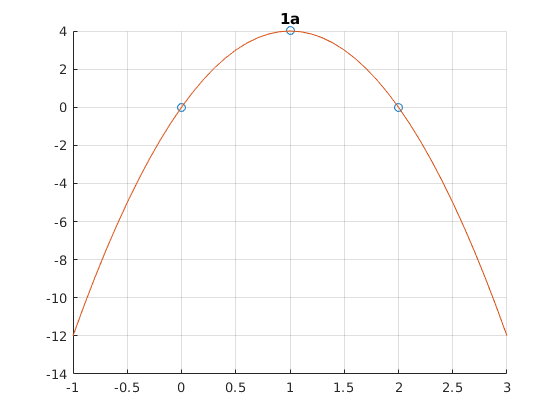

x = [0 1 2];
y = [0 4 0];
p = polyfit(x,y,2);
i = -1:0.1:3;
yi = polyval(p,i);
scatter(x,y);
hold on
plot(i,yi)
title("1a")
grid on
hold off

disp(p)

   -4.0000    8.0000   -0.0000



## question 1b

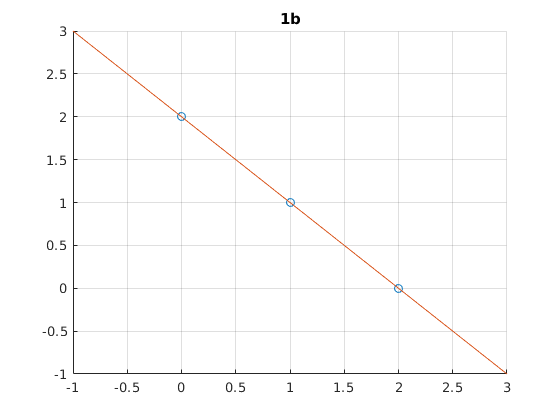

x = [0 1 2];
y = [2 1 0];
p = polyfit(x,y,2);
i = -1:0.1:3;
yi = polyval(p,i);
scatter(x,y);
hold on 
plot(i,yi);
title("1b")
grid on
hold off

disp(p)

     0    -1     2



## question 1bis

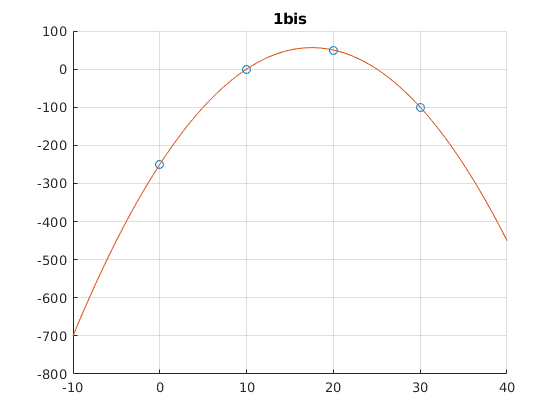

x = [0 10 20 30];
y = [-250 0 50 -100];
p = polyfit(x,y,3);
i = -10:0.1:40;
yi = polyval(p,i);
scatter(x,y);
hold on
plot(i,yi);
title("1bis")
grid on
hold off

disp(p1)

    0.0000   -1.0000   35.0000 -250.0000



## question 2a

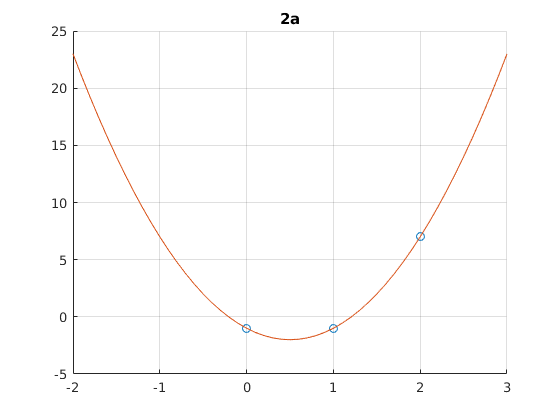

clear
x = [0 1 2];
y = [-1 -1 7];
i = -2:0.1:3;
l = length(i);
scatter(x,y);
hold on
grid on
for t=1:1:l
    yi(t) = lagrange(i(t),x,y);
end
plot(i,yi)
title("2a")
hold off

## question 2b

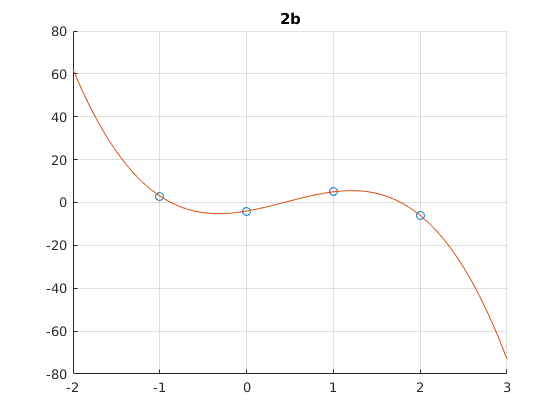

clear
x = [-1 0 1 2];
y = [3 -4 5 -6];
i = -2:0.1:3;
l = length(i);
scatter(x,y)
hold on
grid on
for t=1:1:l
    yi(t) = lagrange(i(t),x,y);
end
plot(i,yi);
title("2b")
hold off

## question 3a

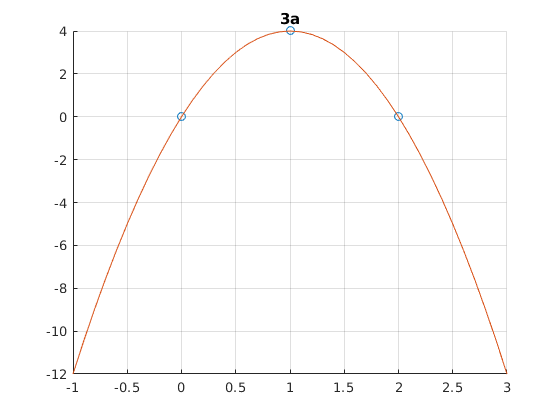

clear
x = [0 1 2];
y = [0 4 0];
i = -1:0.1:3;
l = length(i);
scatter(x,y);
hold on;
grid on;
for t = 1:1:l
    yi(t) = NewtonPoly(x,y,i(t));
end
plot(i,yi);
title("3a")
hold off

## question 3b

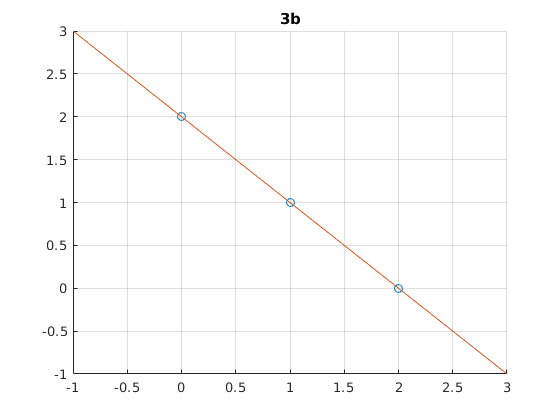

clear
x = [0 1 2];
y = [2 1 0];
i = -1:0.1:3;
l = length(i);
scatter(x,y);
hold on;
grid on;
for t = 1:1:l
    yi(t) = NewtonPoly(x,y,i(t));
end
plot(i,yi);
title("3b")
hold off

## question 3bis

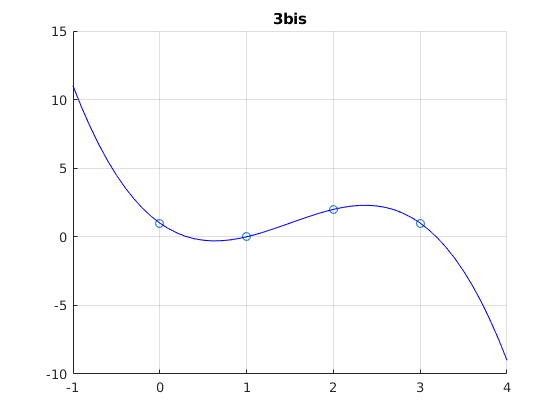

clear
x = [0 1 2 3];
y = [1 0 2 1];
i = -1:0.1:4;
l = length(i);
scatter(x,y);
hold on;
grid on;
for t = 1:1:l
    yi_la(t) = lagrange(i(t),x,y);
    yi_new(t) = NewtonPoly(x,y,i(t));
end
plot(i,yi_la,'r',i,yi_new,'b');
title("3bis")
hold off;